# doble_integracion_lri

performs the integral double of a sampled signal.

## Syntax

pos=doble_integracion_lri(acc,freq)

## Description

`pos=doble_integracion_lri(acc,freq)` performs the integral double of a signal `acc` sampled at `freq` Hz. Previous to the second integral, a lineal resetting mechanism is applied to the velocity by weighting linearly between 1 and 0 during the integration time *T* (LRI method). This is to ensure that *v*(*T*) = 0, a property that you want to fulfill.

				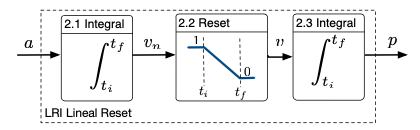

More information: 

Sabatini, A.M.; Martelloni, C.; Scapellato, S.; Cavallo, F. Assessment of walking features from foot inertial 							sensing. *IEEE Trans. Biomed. Eng. ***2005**, *52*, 486–494. 

Alvarez J., Alvarez D., Lopez A., Accelerometry-Based Distance Estimation for Ambulatory Human Motion Analysis, Sensors (2018)  n.18, 4441, 10.3390/s18124441. 						

## Examples

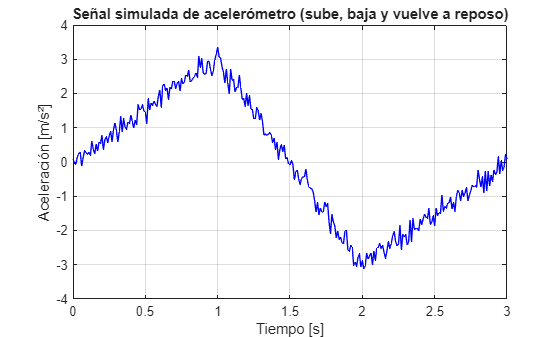

% Simulamos una señal de acelerómetro que sube, baja y vuelve a reposo con ruido
fs = 100;                     % Frecuencia de muestreo [Hz]
t = 0:1/fs:3;                 % Duración de 3 segundos
n = length(t);

% Creamos una forma de aceleración: subida, bajada, reposo
fase1 = linspace(0, 3, round(n/3));       % subida
fase2 = linspace(3, -3, round(n/3));      % bajada
fase3 = linspace(-3, 0, n - 2*round(n/3));% vuelta a reposo
acc_real = [fase1 fase2 fase3];           % concatenamos

% Añadimos ruido gaussiano para simular el sensor
ruido = 0.2*randn(1, n);
acc = (acc_real + ruido)';

% Visualizamos la señal simulada
figure
plot(t, acc, 'b')
xlabel('Tiempo [s]')
ylabel('Aceleración [m/s²]')
title('Señal simulada de acelerómetro (sube, baja y vuelve a reposo)')
grid on

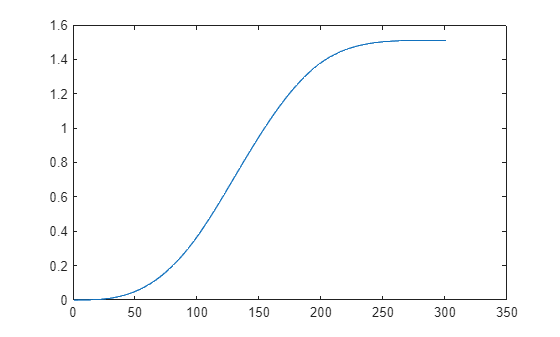


plot(doble_integracion_lri(acc,100));